# Channel Matched Filter Precoder

% Downlink
% Achievable Rate V.S. Power
% Linear Formation and Rectangular Formation

## Global Parameters

clc
clearvars


M1 = 8;
M2 = 8;
M = M1 * M2;

K = 10;

taps = 4;
freq = 20;

time = 100;
cyclic_prefix = 20;

use = 5;

points = 400;

shield = taps + 1;

dn = 0.5;

r = logspace(-2, 2, points);
e = mag2db(r) / 2;

alpha = 0.99;
eta = 500;
mu = 0;


## Distance Matrix

for i = 1 : M
    for j = 1 : M
        dist(i, j) = abs(i - j) * dn;
    end
end
exp_1D = alpha .^ dist;
arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
arg = sqrt(arg);
bsl_1D = besseli(0, arg) ./ besseli(0, eta);
clear dist;

i = 1;
for c1 = 1 : M1
    for r1 = 1 : M2
        j = 1;
        for c2 = 1 : M1
            for r2 = 1 : M2
                dist(i, j) = (c2 - c1) ^ 2 + (r1 - r2) ^ 2;
                j = j + 1;
            end
        end
        i = i + 1;
    end
end
dist = sqrt(dist .* dn);
exp_2D = alpha .^ dist;
arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
arg = sqrt(arg);
bsl_2D = besseli(0, arg) ./ besseli(0, eta);
clear dist;
%{

## Channel Power Delay Profile

phase = (0 : K - 1) / 5;
for l = 1 : taps
    for k = 1 : K
        d1 = exp(-1 * phase(k) * (0 : taps - 1));
        d(l, k) = exp(-1 * phase(k) * (l - 1)) / (sum(d1));
    end
    D1 = diag(d(l, :));
    D(:, :, l) = D1;
end


## Search Tree

for n = 1 : use

    S(:, :, n) = (sqrt(0.5)) * (randn(K, time) + 1i * randn(K, time));

    for l = 1: taps
        D1 = D(:, :, l) .^ (0.5);
        H1 = (sqrt(0.5)) * (randn(M, K) + 1i * randn(M, K));
        
        Hl_exp_1D(:, :, l, n) = conj((exp_1D ^ (0.5)) * H1) * D1;
        Hl_bsl_1D(:, :, l, n) = conj((bsl_1D ^ (0.5)) * H1) * D1;
        Hl_exp_2D(:, :, l, n) = conj((exp_2D ^ (0.5)) * H1) * D1;
        Hl_bsl_2D(:, :, l, n) = conj((bsl_2D ^ (0.5)) * H1) * D1;
    end

    Hv1 = fft(Hl_exp_1D(:, :, :, n), freq, 3);
    Hv2 = fft(Hl_bsl_1D(:, :, :, n), freq, 3);
    Hv3 = fft(Hl_exp_2D(:, :, :, n), freq, 3);
    Hv4 = fft(Hl_bsl_2D(:, :, :, n), freq, 3);
    for v = 1: freq
        Fv = Hv1(:, :, v);
        Wv1(:, :, v) = Fv;
        clear Fv;
        Fv = Hv2(:, :, v);
        Wv2(:, :, v) = Fv;
        clear Fv;
        Fv = Hv3(:, :, v);
        Wv3(:, :, v) = Fv;
        clear Fv;
        Fv = Hv4(:, :, v);
        Wv4(:, :, v) = Fv;
        clear Fv;
    end
    Wl_exp_1D(:, :, :, n) = ifft(Wv1, taps, 3);
    Wl_bsl_1D(:, :, :, n) = ifft(Wv2, taps, 3);
    Wl_exp_2D(:, :, :, n) = ifft(Wv3, taps, 3);
    Wl_bsl_2D(:, :, :, n) = ifft(Wv4, taps, 3);
    
    [AW1(n)] = Signal_Power(taps, Wl_exp_1D(:, :, :, n));
    [AW2(n)] = Signal_Power(taps, Wl_bsl_1D(:, :, :, n));
    [AW3(n)] = Signal_Power(taps, Wl_exp_2D(:, :, :, n));
    [AW4(n)] = Signal_Power(taps, Wl_bsl_2D(:, :, :, n));
    
    % Composite Effect Matrix
    for l = 1 : taps
        E1(:, :, l, n) = (Hl_exp_1D(:, :, l, n))' * (Wl_exp_1D(:, :, l, n));
        E2(:, :, l, n) = (Hl_bsl_1D(:, :, l, n))' * (Wl_bsl_1D(:, :, l, n));
        E3(:, :, l, n) = (Hl_exp_2D(:, :, l, n))' * (Wl_exp_2D(:, :, l, n));
        E4(:, :, l, n) = (Hl_bsl_2D(:, :, l, n))' * (Wl_bsl_2D(:, :, l, n));
    end
end
a1 = 1 / mean(AW1);
a2 = 1 / mean(AW2);
a3 = 1 / mean(AW3);
a4 = 1 / mean(AW4);

% Desired Signal
for n = 1 : use
    for k = 1 : K
        for l = 1 : taps
            gk1(k, :, n, l) = a1 * mean(E1(k, k, l, :), 4) * S(k, :, n);
            gk2(k, :, n, l) = a2 * mean(E2(k, k, l, :), 4) * S(k, :, n);
            gk3(k, :, n, l) = a3 * mean(E3(k, k, l, :), 4) * S(k, :, n);
            gk4(k, :, n, l) = a4 * mean(E4(k, k, l, :), 4) * S(k, :, n);
        end
    end
end
g1 = sum(gk1, 4);
clear gk1;
g2 = sum(gk2, 4);
clear gk2;
g3 = sum(gk3, 4);
clear gk3;
g4 = sum(gk4, 4);
clear gk4;

% Transmit Signal
for n = 1 : use
    for l = 1 : taps
        for i = 1 : time - shield
            Xk1(:, i, n, l) = a1 * (Wl_exp_1D(:, :, l, n)) * S(:, i + l, n);
            Xk2(:, i, n, l) = a2 * (Wl_bsl_1D(:, :, l, n)) * S(:, i + l, n);
            Xk3(:, i, n, l) = a3 * (Wl_exp_2D(:, :, l, n)) * S(:, i + l, n);
            Xk4(:, i, n, l) = a4 * (Wl_bsl_2D(:, :, l, n)) * S(:, i + l, n);
        end
    end
end
X1 = sum(Xk1, 4);
clear Xk1;
X2 = sum(Xk2, 4);
clear Xk2;
X3 = sum(Xk3, 4);
clear Xk3;
X4 = sum(Xk4, 4);
clear Xk4;

% Channel Output Signal
for n = 1 : use
    for l = 1 : taps
        for i = shield : time - shield
            yk1(:, i, n, l) = (Hl_exp_1D(:, :, l, n))' * X1(:, i - l, n);
            yk2(:, i, n, l) = (Hl_bsl_1D(:, :, l, n))' * X2(:, i - l, n);
            yk3(:, i, n, l) = (Hl_exp_2D(:, :, l, n))' * X3(:, i - l, n);
            yk4(:, i, n, l) = (Hl_bsl_2D(:, :, l, n))' * X4(:, i - l, n);
        end
    end
end
y1 = sum(yk1, 4);
clear yk1;
y2 = sum(yk2, 4);
clear yk2;
y3 = sum(yk3, 4);
clear yk3;
y4 = sum(yk4, 4);
clear yk4;

% Effective Noise
z1(:, shield : time - shield, :) = y1(:, shield : time - shield, :) - g1(:, shield : time - shield, :);
z2(:, shield : time - shield, :) = y2(:, shield : time - shield, :) - g2(:, shield : time - shield, :);
z3(:, shield : time - shield, :) = y3(:, shield : time - shield, :) - g3(:, shield : time - shield, :);
z4(:, shield : time - shield, :) = y4(:, shield : time - shield, :) - g4(:, shield : time - shield, :);

F1 = sum(mean(E1, 4), 3);
F2 = sum(mean(E2, 4), 3);
F3 = sum(mean(E3, 4), 3);
F4 = sum(mean(E4, 4), 3);
for n = 1 : use
    for k = 1 : K
        Sn1(k, :, n) = abs(a1 * F1(k, k)) ^ 2 * r(:);
        Sn2(k, :, n) = abs(a2 * F2(k, k)) ^ 2 * r(:);
        Sn3(k, :, n) = abs(a3 * F3(k, k)) ^ 2 * r(:);
        Sn4(k, :, n) = abs(a4 * F4(k, k)) ^ 2 * r(:);
        
        Vn1(k, :, n) = var(z1(k, :, n), 0, 2) * r(:) + 1;
        Vn2(k, :, n) = var(z2(k, :, n), 0, 2) * r(:) + 1;
        Vn3(k, :, n) = var(z3(k, :, n), 0, 2) * r(:) + 1;
        Vn4(k, :, n) = var(z4(k, :, n), 0, 2) * r(:) + 1;
        
        SNR1(k, :, n) = (Sn1(k, :, n)) ./ (Vn1(k, :, n));
        SNR2(k, :, n) = (Sn2(k, :, n)) ./ (Vn2(k, :, n));
        SNR3(k, :, n) = (Sn3(k, :, n)) ./ (Vn3(k, :, n));
        SNR4(k, :, n) = (Sn4(k, :, n)) ./ (Vn4(k, :, n));
        
        Rk1(k, :, n) = log2(1 + (SNR1(k, :, n)));
        Rk2(k, :, n) = log2(1 + (SNR2(k, :, n)));
        Rk3(k, :, n) = log2(1 + (SNR3(k, :, n)));
        Rk4(k, :, n) = log2(1 + (SNR4(k, :, n)));
    end
end

R1 = 0.5 * sum(mean(Rk1, 3), 1);
clear Sn1 Vn1 SNR1 Rk1;
R2 = 0.5 * sum(mean(Rk2, 3), 1);
clear Sn2 Vn2 SNR2 Rk2;
R3 = 0.5 * sum(mean(Rk3, 3), 1);
clear Sn3 Vn3 SNR3 Rk3;
R4 = 0.5 * sum(mean(Rk4, 3), 1);
clear Sn4 Vn4 SNR4 Rk4;
%}

## Mathematical Results

Sn0 = (M / K) * r;
Vn1 = ((trace(exp_1D * exp_1D')) / M) * r + 1;
SNR1 = Sn0 ./ Vn1;

Vn2 = ((trace(bsl_1D * bsl_1D')) / M) * r + 1;
SNR2 = Sn0 ./ Vn2;

Vn3 = ((trace(exp_2D * exp_2D')) / M) * r + 1;
SNR3 = Sn0 ./ Vn3;

Vn4 = ((trace(bsl_2D * bsl_2D')) / M) * r + 1;
SNR4 = Sn0 ./ Vn4;

R1 = (K / 2) * log2(1 + SNR1);
R2 = (K / 2) * log2(1 + SNR2);
R3 = (K / 2) * log2(1 + SNR3);
R4 = (K / 2) * log2(1 + SNR4);

factor = (time) / (time + cyclic_prefix);

R1 = factor * R1;
R2 = factor * R2;
R3 = factor * R3;
R4 = factor * R4;


## Plots

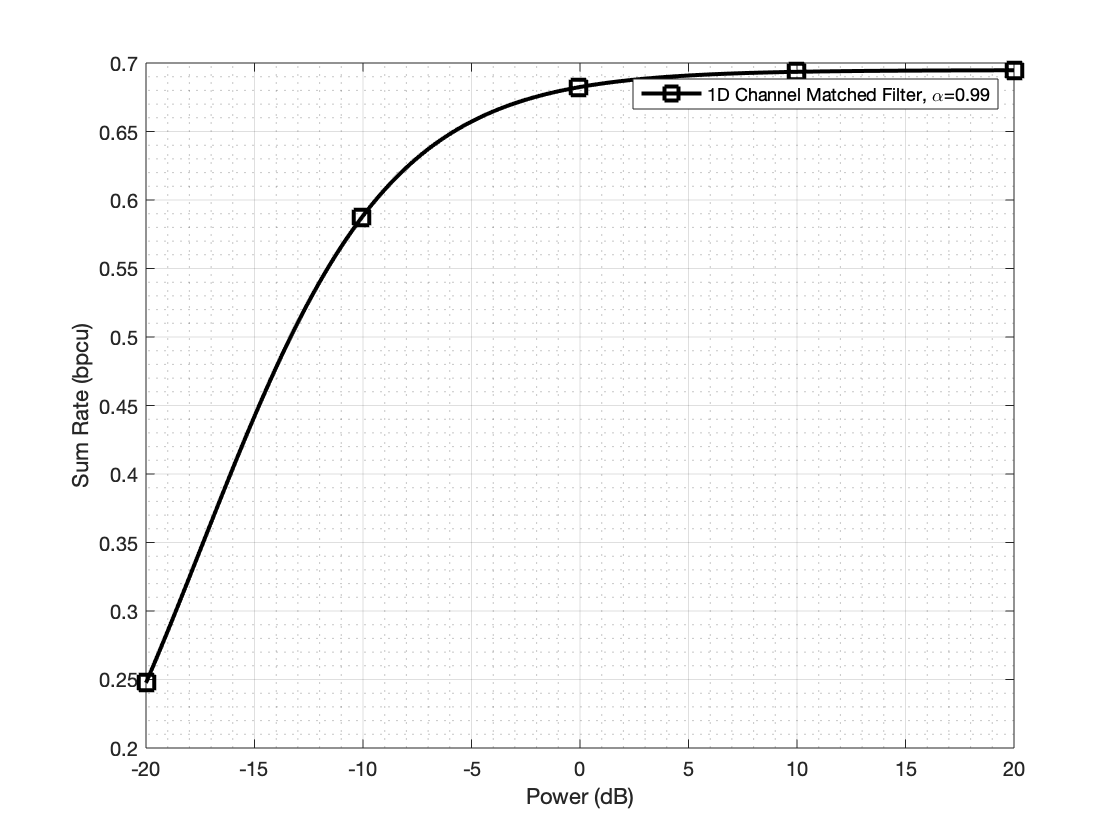

index = [1, 100, 200, 300, 400];

angel = strcat('\pi/', num2str(pi / mu));
if (mu == 0)
    angel = num2str(0);
end

name_a = '1D Channel Matched Filter';
name_b = '2D Channel Matched Filter';

name1 = strcat(name_a, ', \alpha=', num2str(alpha));
% name2 = strcat(name_a, ', \eta=', num2str(eta), ', \mu=', angel);
name2 = strcat(name_a, ', \eta=', num2str(eta));
name3 = strcat(name_b, ', \alpha=', num2str(alpha));
% name4 = strcat(name_b, ', \eta=', num2str(eta), ', \mu=', angel);
name4 = strcat(name_b, ', \eta=', num2str(eta));

x_label = 'Power (dB)';
y_label = 'Sum Rate (bpcu)';

style = '-ks';

figure;
plot(e, R1, style, 'DisplayName', name1, 'MarkerIndices', index, 'MarkerSize', 10);

xlabel(x_label, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;

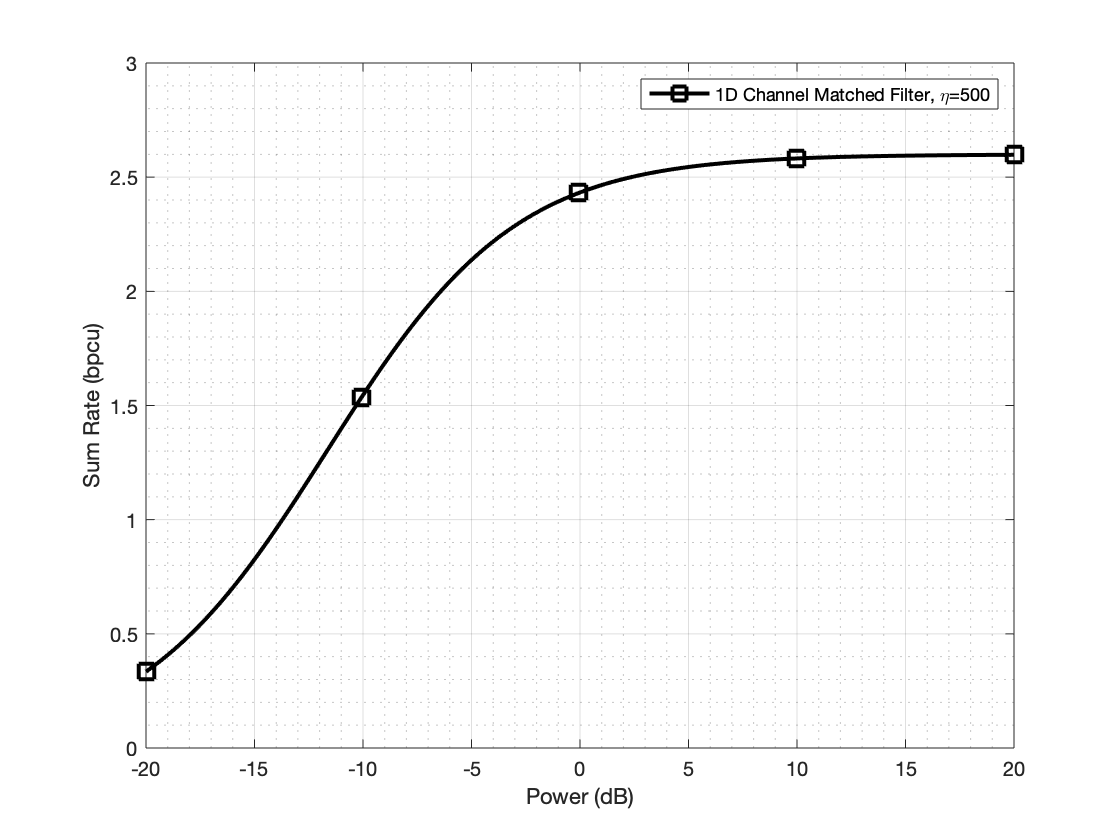



figure;
plot(e, R2, style, 'DisplayName', name2, 'MarkerIndices', index, 'MarkerSize', 10);

xlabel(x_label, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;

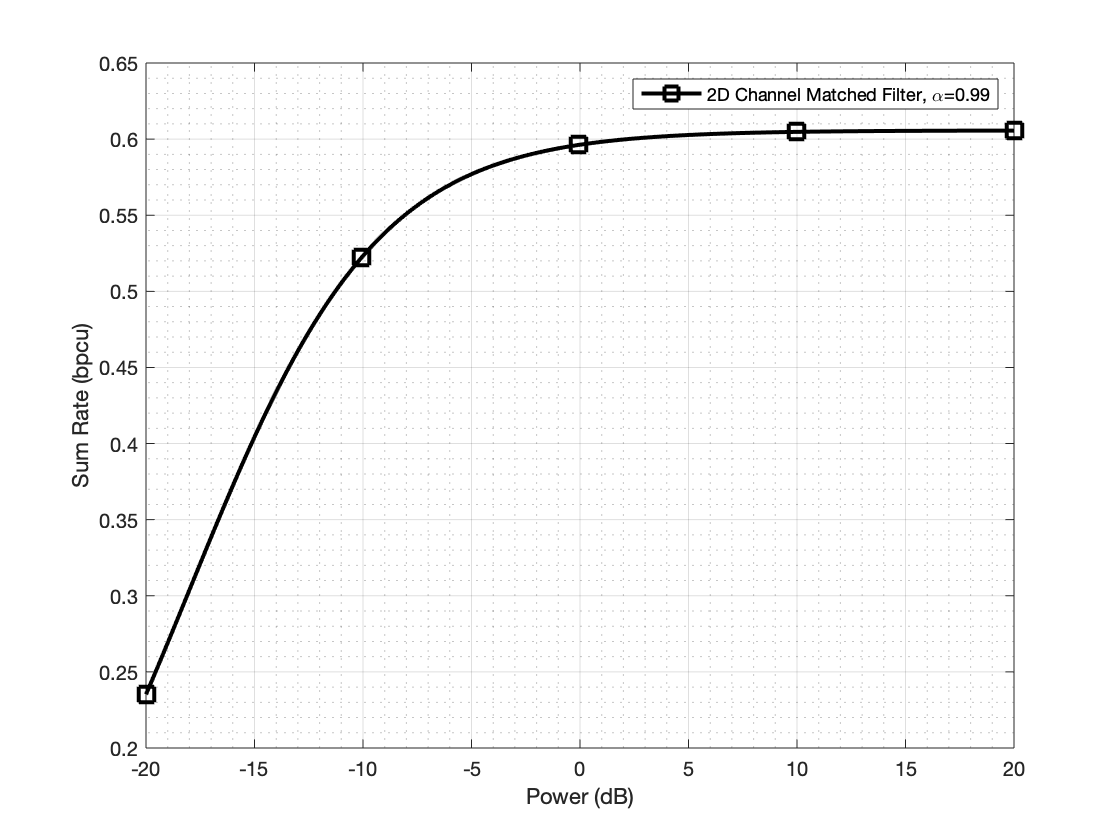


figure;
plot(e, R3, style, 'DisplayName', name3, 'MarkerIndices', index, 'MarkerSize', 10);

xlabel(x_label, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;

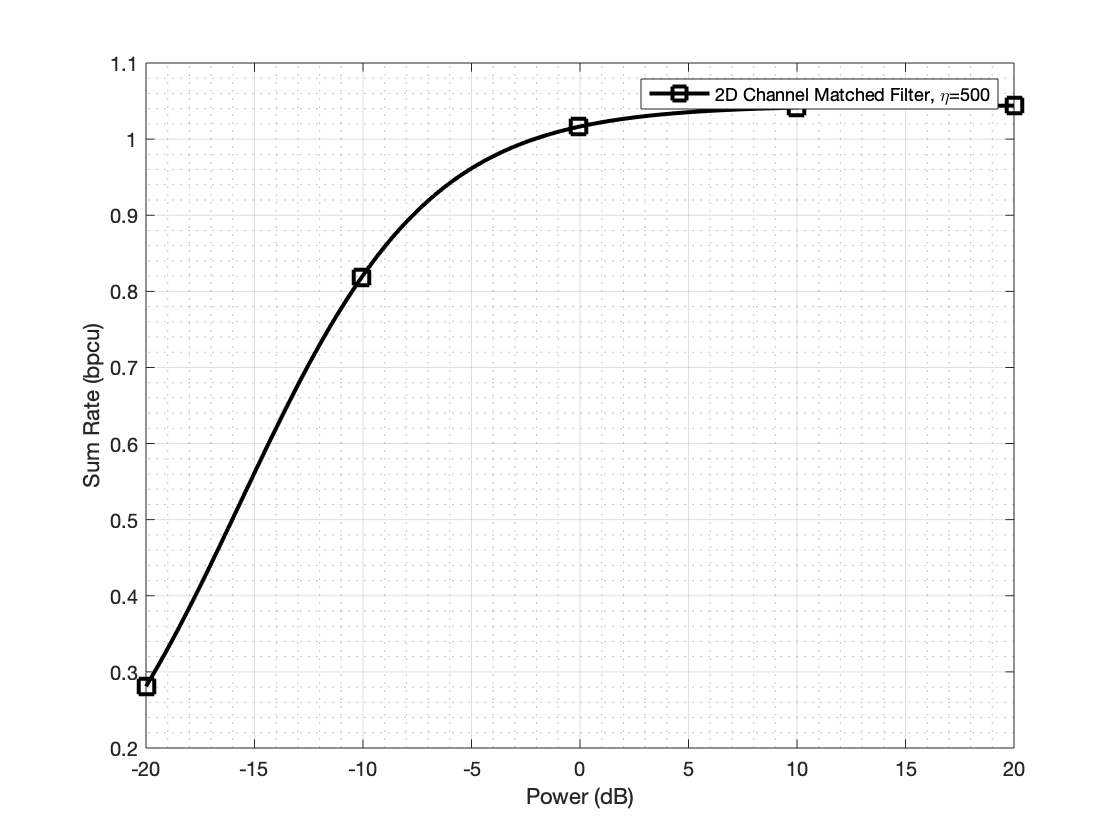



figure;
plot(e, R4, style, 'DisplayName', name4, 'MarkerIndices', index, 'MarkerSize', 10);

xlabel(x_label, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;